## Introduction

This interactive notebook steps through examples in Fink et al.'s (2022) manuscript: *From pre-processing to advanced dynamic modeling of pupil data*. If using anything from this script, please cite: 

- Fink, L., Simola, J., Tavano, A., Lange, E. B., Wallot, S., & Laeng, B. (submitted). From pre-processing to advanced dynamic modeling of pupil data. [https://doi.org/10.31234/osf.io/wqvue](https://doi.org/10.31234/osf.io/wqvue)

In some cases, it may also be applicable to cite: 

- Fink, L. K., Hurley, B. K., Geng, J. J., & Janata, P. (2018). A linear oscillator model predicts dynamic temporal attention and pupillary entrainment to rhythmic patterns. *Journal of Eye Movement Research*, *11*(2). [https://doi.org/10.16910/jemr.11.2.12](https://doi.org/10.16910/jemr.11.2.12) 

Note that a subset of the analysis approaches discussed below (e.g., convolution, time-frequency analyses) were presented during a two-hour Pupil Time Series workshop, which was part of a larger Pupillometry Workshop, held April 4-5th, 2022, at the University of Oslo, Centre for Interdisciplinary Studies in Rhythm, Time, and Motion (RITMO). More information about the workshop can be [found here](https://www.uio.no/ritmo/english/projects/ritpart/events/workshops/2022/pupillometry/index.html). A link to the two-hour video and accompanying code tutorial from the workshop are available in [this GitHub repository](https://github.com/lkfink/RITMO_pupil_workshop). 

#### About this code:

The goal of this interactive notebook is to provide users with a more in-depth understanding of some of the most critical concepts discussed in Fink et al.'s (submitted) manuscript. All figures in the paper can be recreated using this code and the accompanying toy data set. This notebook also contains additional references and discussion of key time series concepts. 

Contact: lauren.fink@ae.mpg.de 

## Tutorial

### Load toy data set

As long as you have not moved any files around in the folder you downloaded that contains this script, you should have no problem loading the appropriate files and functions. 

These toy data come from the much larger data set reported in this paper: 

- Lange, E. B., Zweck, F., & Sinn, P. (2017). Microsaccade-rate indicates absorption by music listening. *Consciousness and cognition*, *55*, 59-78.

Note that in the toy data set provided, we have already pre-processed the pupil data by removing data during blinks and saccades, linearly interpolating missing data, high-pass filtering at .05 Hz, downsampling to 100 Hz, and z-scoring per trial. Pre-processing steps are not the focus of this tutorial, but rather warrant their own in depth consideration and discussion (see Section 2 of the corresponding paper). 

The toy dataset consists of all participants' pupil traces recorded while listening to two different instrumental music clips. 

% Get name of directory containing this file
working_dir = fileparts(matlab.desktop.editor.getActiveFilename);

% Load data set (loads into structure called pd)
load(fullfile(working_dir, 'Fink_toydata.mat'))

## Explore basics of time series

In this section we plot a few time series and explore some fundamental concepts. 

### Plot time series

Let's plot one subject's pupil trace for one stimulus.

% Define parameters for user controls
subs = unique(pd.data.subject);
minsubs = min(subs);
maxsubs = max(subs);

stims = unique(pd.data.stimulus);
minstims = min(stims);
maxstims = max(stims);

Select which subject and stimulus you would like to plot.

Stimulus 6 is Fourtet's *She moves she*

Stimulus 20 is Duke Ellington's *Take the A Train*

N.B. To re-recreate the figures from the paper, please set the stimulus to 20. 

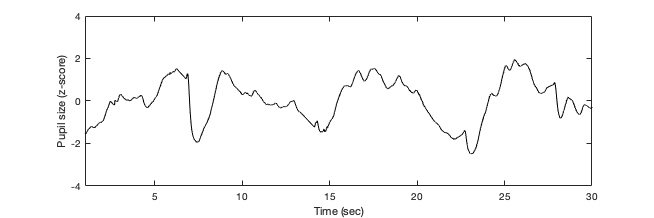

selected_sub =16;
selected_stim = 20;
singlesub_pup = cell2mat(pd.data.pupil(pd.data.subject==selected_sub & pd.data.stimulus==selected_stim));

% Plot
figure()
xscale = samps2secs(singlesub_pup, pd.pupil_info.Fs.cleaned);
plot(xscale, singlesub_pup, 'k', 'LineWidth',1)
ylim([-4 4])
xlim([1 30])
ylabel('Pupil size (z-score)')
xlabel('Time (sec)')
set(gcf,'Units', 'inches', 'Position',[5 5 15 5])

If you explore the pupil data for different participants, you will see that some pupil time series are cleaner than others.

- Look at the data of subject 1 vs. 3. What seems different? The data of subject 1 are less "noisy" than sub 3. What could make subject 3's data look more like subject 1? (answer: a low pass filter that would remove high frequency noise). 

- The toy data provided here were already pre-processed with missing data linearly interpolated. Sometimes so much continigous data may be missing that interpolation looks unnatural. Check out sub 5, stim 20. Look for the visible straight lines going between noisy chunks of data. This type of data will not be a problem for some types of analysis but may be for others. Try to think through what kind of effects it may have (e.g., steep edges create power in higher frequency bands). 

### Time series vs. averages

To gain a sense of why it might be interesting to look at a full time series, let's visualize what is going on when we use means vs time series.

First, let's plot the mean of our time series for the stimulus selected above vs. the mean over the whole stimulus. Error represents the variability across participants. 

Check this box if you would like to see the standard deviation, otherwise the standard error of the mean will be plotted. 

plot_std = false;% Flag whether to plot std (check) or not

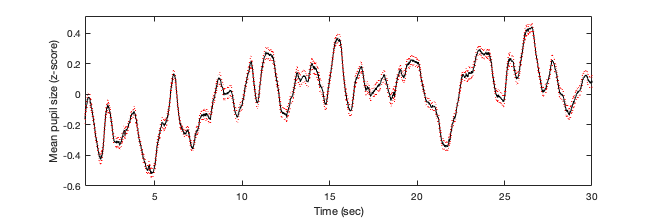

% Get the average pupil time series for selected stimulus
pupdata_selected_stim = cell2mat(pd.data.pupil(pd.data.stimulus==selected_stim));
avgpup = mean(pupdata_selected_stim);
stdpup = std(pupdata_selected_stim);
sempup = stdpup / size(pupdata_selected_stim, 1);

% Plot time series average
figure()
xscale = samps2secs(avgpup, pd.pupil_info.Fs.cleaned);
plot(xscale, avgpup, 'k', 'LineWidth',1)
hold on
if plot_std
    errordata = stdpup;
else
    errordata = sempup;
end
plot(xscale, avgpup+errordata, ':r', 'LineWidth',1) % upper error
hold on
plot(xscale, avgpup-errordata, ':r', 'LineWidth',1) % lower error
ylim([min(avgpup-errordata)*1.1 max(avgpup+errordata)*1.1])
xlim([1 30])
ylabel('Mean pupil size (z-score)')
xlabel('Time (sec)')
set(gcf,'Units', 'inches', 'Position',[5 5 15 5])

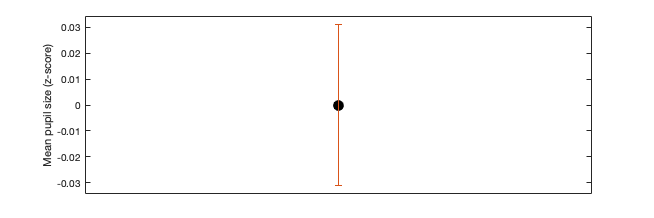

% Get the average pupil size for selected stimulus, for each subject
avgpup_subs = mean(pupdata_selected_stim, 2); % 2 for second dim
stdpup_subs = std(pupdata_selected_stim,0,2); %no weighting, 2nd dim
sempup_subs = stdpup_subs / size(pupdata_selected_stim, 1);

% Choose which error data to proceed with
if plot_std
    errordata = stdpup_subs;
else
    errordata = sempup_subs;
end

% Get mean over all subs
mean_err = mean(errordata);
mean_subs = mean(avgpup_subs);
% Plot averages of time series
figure()
plot(1,mean_subs, 'ko', 'MarkerFaceColor','k', 'MarkerSize',10)
hold on
errorbar(1,mean_subs,mean_subs-mean_err,mean_subs+mean_err);
ylim([min(mean_subs-mean_err)*1.1 max(mean_subs+mean_err)*1.1])
ylabel('Mean pupil size (z-score)')
set(gca,'xtick',[])
set(gcf,'Units', 'inches', 'Position',[5 5 15 5])

As we can see from these two plots, we get vastly different kinds of information depending on the approach we take. It is clear from the top plot that there are certain moments in time when the pupil size average is well above or below zero. For example, if looking at the data for stimulus 6, there seem to be three major peaks in our time series (around 400, 1500, 2200). For stimulus 20, there are no such clear section breaks, but rather a lot of fluctuation throughout. When averaging over time (bottom plot), we lose all information related to the temporal dynamics of changes in pupil size. We could relate this single value to a single-valued mean of some musical feature of interest, but: 

*What if we want to relate the continuous pupil time series to the continuous musical stimulus participants were listening to? *

### Music as a time series

If you want to listen to the stimulus selected above, use the following controls: 

% Get the amplitude envelope of one music stimulus
music = pd.stimulus_info.audio_original{pd.stimulus_info.ID == selected_stim}; % Our selected stimulus
player = audioplayer(music, pd.stimulus_info.Fs.original);

 
play(player)

 
pause(player)

 
resume(player)

 
stop(player)

Let's plot the raw audio.

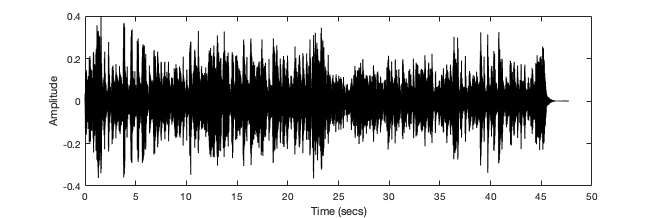

figure()
xscale = samps2secs(music(:,1), pd.stimulus_info.Fs.original);
plot(xscale, music(:,1), 'k')
xlabel('Time (secs)')
ylabel('Amplitude')
set(gcf,'Units', 'inches', 'Position',[5 5 15 5])

#### Filtering 

As we can see from the plot above, our audio signal is really densely sampled. Do we actually think the pupil could keep up with changes at 44.1k? - absolutely not! The pupil's ability to move (constrict / dilate) seems to occur mostly in the 0-4 Hz range. When filtering, you should always set the frequency cut-off to be at least double the highest frequency you are interested in. So in this case, we want to make sure we can observe activity up to 4 Hz, therefore, our frequency cutoff should be at least 8 Hz. We can low-pass filter at 10 Hz just to be safe. 

Also, our pupil data are sampled at 100 Hz. We should downsample our audio data to match our pupil data. It is important that the pupil and audio signals are the same length for some of the analysis techniques we wish to discuss below. Further, we can also see from the waveform that the audio amplitude is symmetric about zero, so we can proceed with only the upper portion of our amplitude envelope. 

Below, we plot our new audio signal after extracting the upper amplitude envelope, low-pass filtering at 10 Hz, downsampling to 100 Hz, and z-scoring. 

To get an idea of what a filter does, you can mess around with the frequency of the low pass filter. Note though, that some frequencies might require a different order or type of filter. Right now the order is set to 3rd, and the type of filter is Butterworth. Designing good filters is not the focus of this tutorial, but we can recommend the following article: 

- de Cheveigné, A., & Nelken, I. (2019). Filters: when, why, and how (not) to use them. *Neuron*, *102*(2), 280-293.

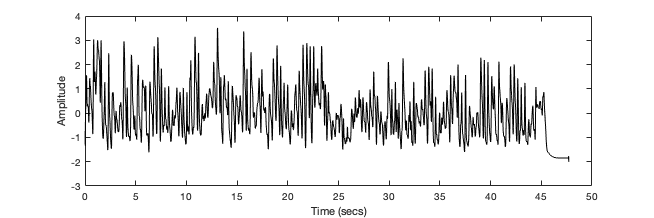

lowpass_cutoff_freq = 10;
N = 100*.05; % 50ms window for envelope function
[YUPPER,YLOWER] = envelope(music, N, 'rms'); % Our envelope. Proceed with just the upper portion (they are symmetrical)
[b,a] = butter(3, lowpass_cutoff_freq/(pd.stimulus_info.Fs.original/2), 'low'); % lowpass filter envelope at 10Hz.
filtaud = filtfilt(b,a,YUPPER(:,1));
music_env = zscore(filtaud);
[p,q] = rat(pd.pupil_info.Fs.cleaned / pd.stimulus_info.Fs.original); % desired fs / original fs
music_env_ds = resample(music_env, p, q);

figure()
xscale = samps2secs(music_env_ds, pd.pupil_info.Fs.cleaned);
plot(xscale, music_env_ds, 'k')
xlabel('Time (secs)')
ylabel('Amplitude')
set(gcf,'Units', 'inches', 'Position',[5 5 15 5])

begin = pd.pupil_info.Fs.cleaned * 5; % 5 secs into music
datalen = pd.pupil_info.Fs.cleaned * 30; % want to take 30 secs of data
music_excerpt = music_env_ds(begin:begin+datalen);

Notice that at lower cutoff frequencies our stimulus time course looks more on the scale of what we might imagine from the pupil. 

Note that the pupil data provided in this toydata set are from seconds 5 - 35 of the stimulus, so we will now trim our audio data to match our pupil data. 

### Relating our two time series

*Now how can we relate the two signals (music and pupil)?*

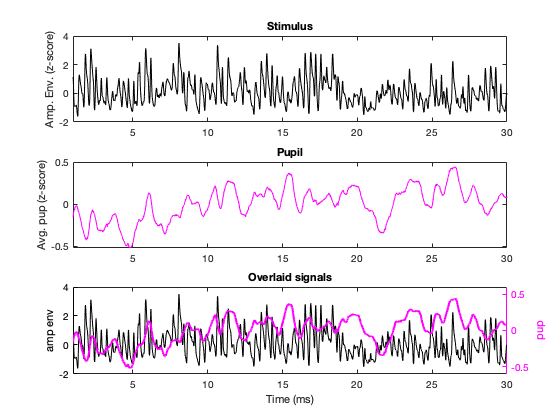

figure()
% plot stimulus
subplot(3,1,1) 
xscale = samps2secs(music_excerpt, pd.stimulus_info.Fs.downsampled);
plot(xscale, music_excerpt, 'k')
xlim([1 30])
ylabel('Amp. Env. (z-score)')
title('Stimulus')
hold on
% plot pupil 
subplot(3,1,2)
plot(xscale, avgpup, 'm')
ylabel('Avg. pup (z-score)')
title('Pupil')
xlim([1 30])

% plot the two traces overlaid on each other
subplot(3,1,3)
yyaxis left
plot(xscale, music_excerpt, 'k')
ylabel('amp env')
hold on
yyaxis right
plot(xscale, avgpup, 'm', 'LineWidth',2)
ylabel('pup')
xlabel('Time (ms)')
xlim([1 30])
ax = get(gca);
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'm';
title('Overlaid signals')

There are a variety of possible options for how to assess their relation. We will step through a few options. 

## Convolution

Perhaps our goal is to understand the transfer function between the two signals above. We can think of our music as a function m(t) and our pupil as a function p(t). To understand the relation between these two functions, we want to solve for a third function that relates the two. 

Actually, though, we don't need to solve for such a transfer function because it has already been empirically derived by others! For example Hoeks & Levelt (1993) defined the pupil impulse response function (PRF) as follows: 


$$\textrm{PRF}=t^n e^{\left(-\;\frac{\textrm{nt}}{t_{\max } }\right)}$$


*t* = delay until pupil size returns to basline

*n* = number of neural signaling steps between impulse and pupil response

*t_max* = pupil response peak latency 

To determine the parameters of this function, they had participants listen to auditory tones and respond with a button press. 

From known input and measured output, they fit the following function that defines the input-output relationship:

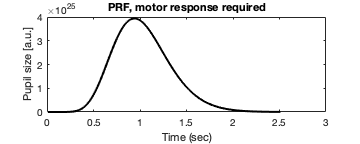

figure()
prf = genPRF(pd.pupil_info.Fs.cleaned, 1);
xscale = samps2secs(prf, pd.pupil_info.Fs.cleaned); % convert to secs
plot(xscale, prf, 'k', 'Linewidth', 2)
xlim([0 3]);
ylimMotor = get(gca, 'Ylim');
xlabel('Time (sec)')
ylabel('Pupil size [a.u.]')
title('PRF, motor response required')
set(gcf,'Units', 'inches', 'Position',[5 5 5 2])

Later, other researchers (e.g., McCloy et al., 2016) showed that the constants defined in this response function differ, depending on whether participants need to make a button press. If no button press is required the pupil takes less time to return to baseline. The amplitude of the response is also less, though that is hard to tell from the scaling of these axes.

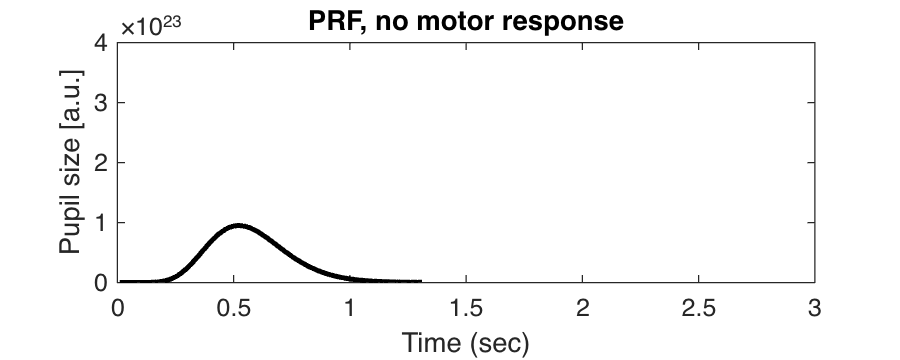

prf = genPRF(pd.pupil_info.Fs.cleaned, 0); % 0 for no motor response

% plot
figure()
xscale = samps2secs(prf, pd.pupil_info.Fs.cleaned);
plot(xscale, prf, 'k', 'Linewidth', 2)
xlim([0 3]) % so can compare with previous prf
ylim(ylimMotor/100) % scale axis so comparable and visible
xlabel('Time (sec)')
ylabel('Pupil size [a.u.]')
title('PRF, no motor response')
set(gcf,'Units', 'inches', 'Position',[5 5 5 2])

Still later, others have shown that the parameters of the PRF are highly consistent within an individual but do vary across individuals (Denison et al., 2020). Therefore, future research might consider a task to first calculate each individual's PRF. 

#### Further Reading

- Hoeks, B., & Levelt, W. J. (1993). Pupillary dilation as a measure of attention: A quantitative system analysis. *Behavior Research methods, instruments, & computers*, *25*(1), 16-26.

- McCloy, D. R., Larson, E. D., Lau, B., & Lee, A. K. (2016). Temporal alignment of pupillary response with stimulus events via deconvolution. *The Journal of the Acoustical Society of America*, *139*(3), EL57-EL62.

- Denison, R. N., Parker, J. A., & Carrasco, M. (2020). Modeling pupil responses to rapid sequential events. *Behavior research methods*, *52*(5), 1991-2007.

### Building intuition about how convolution works

Let's mess around a bit with impulse trains and our pupil response function. 

Set the inter-onset-interval of the impulses you want to input (in ms):

impulseIOI = 3000;

Next decide if you want all impulses to be the same amplitude or different. The number you input will accent every x impulse (e.g. by inputting 4, every 4th impulse will be greater in amplitude). 

weight = 0;

Next decide whether you want to use the motor or non-motor PRF. Check the box for motor

motor = false;

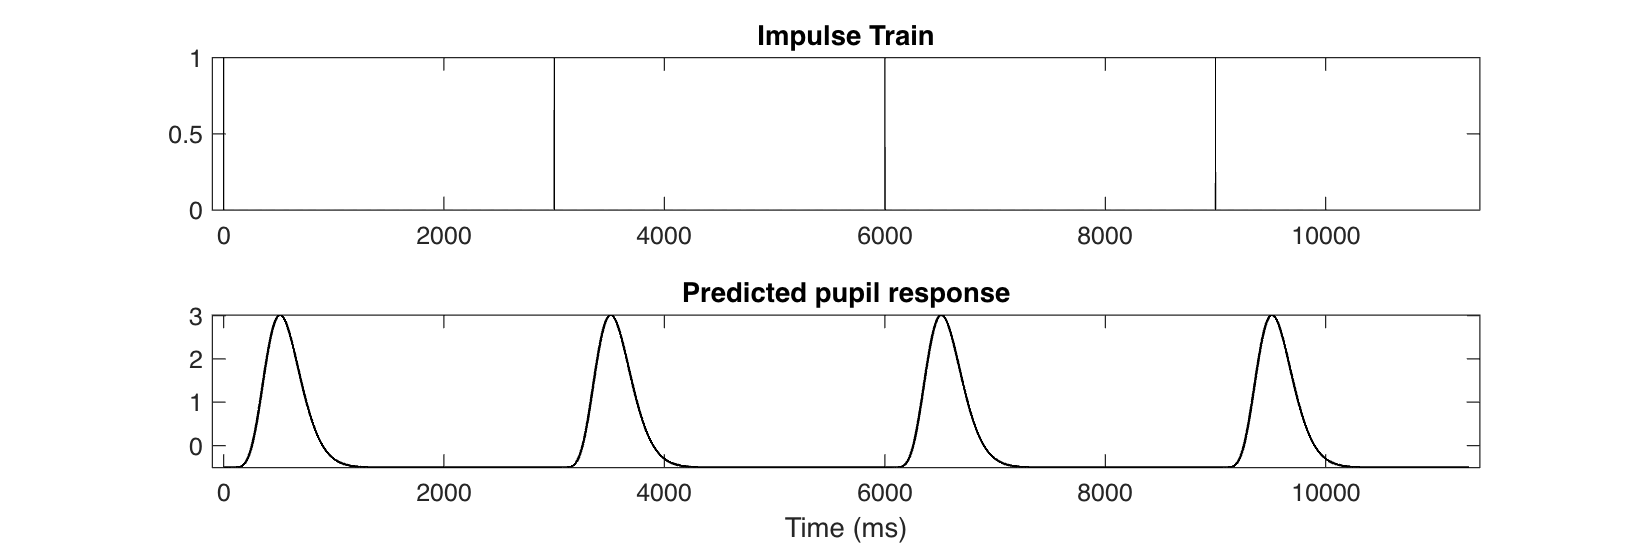

% generate series of impulses
impulseTrain = zeros(1,10000);              % initiate empty time series, 10 secs long
impulseTrain(1:impulseIOI:end) = 1;         % insert event every IOI
impulseTrain(1:impulseIOI*weight:end) = 2;  % insert event every IOI

% convolve impulses with PRF

% Generate PRF and predicted pupil trace
prf = genPRF(1000, motor); % 1000 for Fs so keep things in msecs, 1 for motor response
predpup = conv(impulseTrain, prf, 'full');
pred = zscore(predpup); % normalize

% Plot
figure()
subplot(2,1,1)
plot(impulseTrain, 'k')
xlim([-100 numel(pred)+100])
title('Impulse Train')
hold on

subplot(2,1,2)
plot(pred, 'k', 'Linewidth', 1)
xlim([-100 numel(pred)+100])
title('Predicted pupil response')
xlabel('Time (ms)')
set(gcf,'Units', 'inches', 'Position',[1 1 15 5])

### Predicting pupil data

Let's return to our question earlier about relating our stimulus to our recorded pupil data. 

One question we might have is whether the recorded pupil data reflects what would be predicted by convolving our stimulus with the pupillary response function. While participants were listening to the music included in the toy dataset, they did not make any responses, so we will use the non-motor PRF. 

Below we plot the predicted pupil data vs. the recorded pupil data (averaged across participants). 

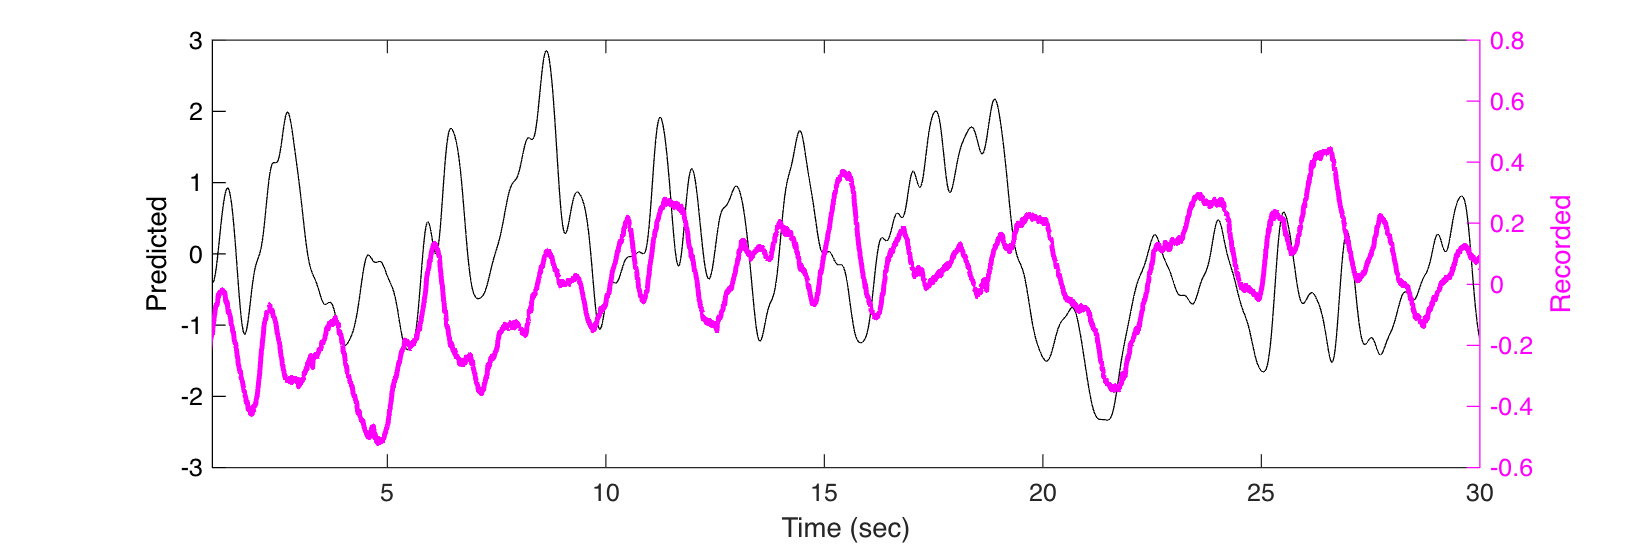

% Generate PRF and predicted pupil trace
prf = genPRF(pd.pupil_info.Fs.cleaned, 0);
predpup = conv(music_env_ds, prf, 'full'); % do convolution on full music
predpup = predpup(begin:begin+datalen); % now cut to our 30 secs
pred = zscore(predpup); % normalize

% Plot
figure()
xscale = samps2secs(pred, pd.pupil_info.Fs.cleaned);
% plot prediction in black
yyaxis left
plot(xscale, pred', 'k')
ylabel('Predicted')
hold on
% plot pupil in magenta
yyaxis right
plot(xscale, avgpup, 'm', 'LineWidth',2)
xlim([1 30])
xlabel('Time (sec)')
ylabel('Recorded')
set(gcf,'Units', 'inches', 'Position',[5 5 15 5])
ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'm';

We could also go in the reverse direction, and predict the pupil trace, given the music played and the convolution kernal. The code below illustrates this concept and creates **Fig. 1** of the corresponding paper: 

N.B. stimulus selection above should be set to 20 to recreate the exact figure. 

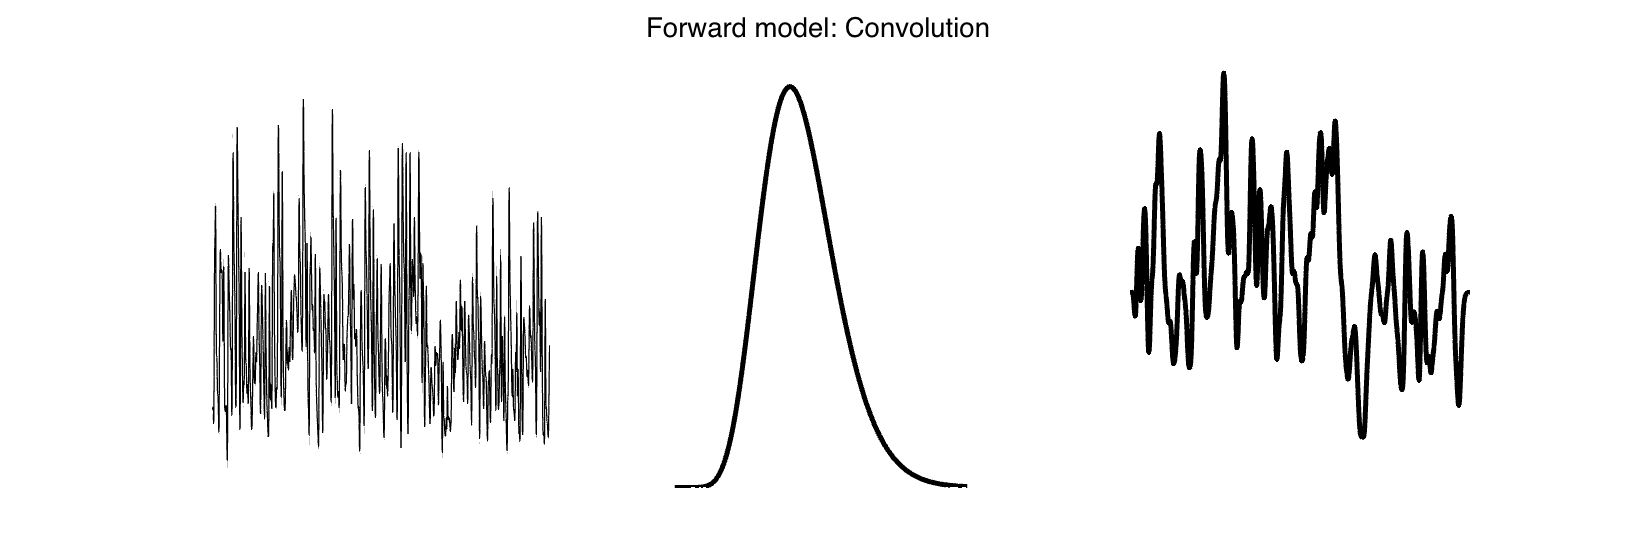

%% Figure 1
%-------------------------------------------------------------------------%
% Convolution example (Fig. 1A) 
%-------------------------------------------------------------------------%

% Generate PRF and predicted pupil trace
prf = genPRF(100, 0);
predpup = conv(music_excerpt, prf, 'full');
pred = zscore(predpup); % normalize

% Plot
figure()
subplot(1,3,1)
plot(music_excerpt, 'k')
axis off
hold on 

subplot(1,3,2)
plot(prf, 'k', 'Linewidth', 2)
axis off

subplot(1,3,3)
plot(pred, 'k', 'Linewidth', 2)
axis off
sgtitle('Forward model: Convolution')
set(gcf,'Units', 'inches', 'Position',[1 1 15 5])

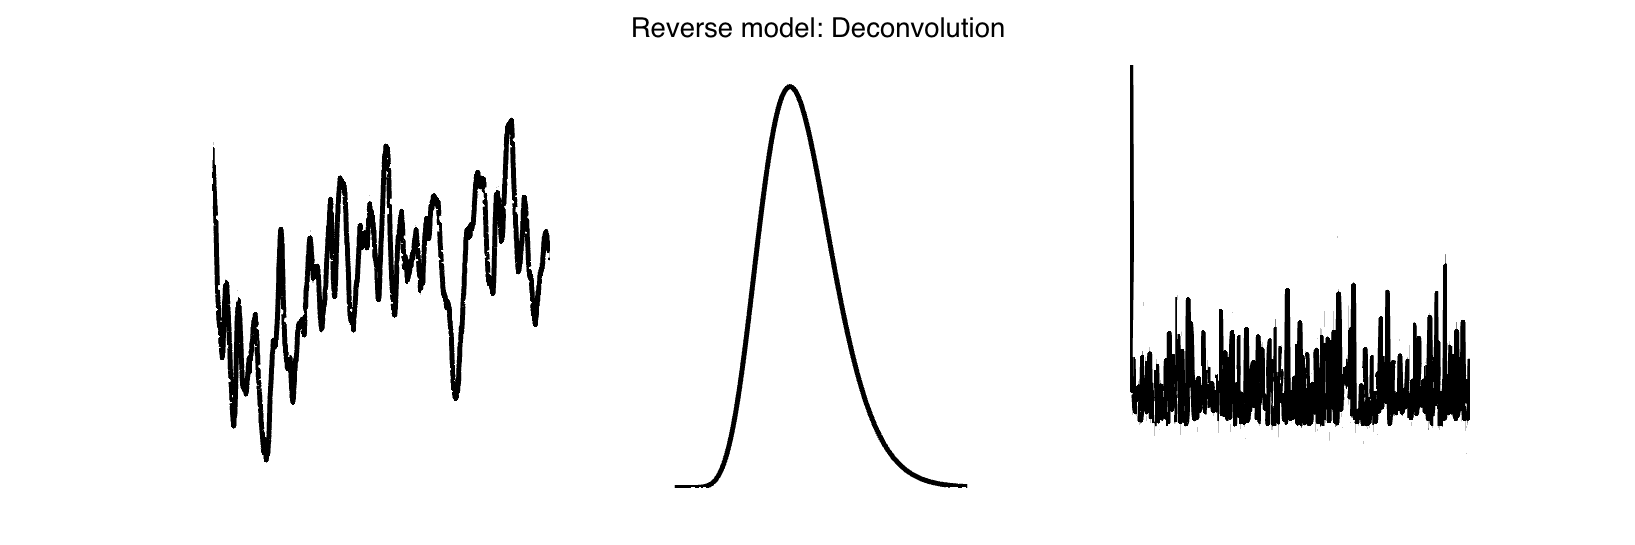


%%
%-------------------------------------------------------------------------%
% Deconvolution example (Fig. 1B) 
%-------------------------------------------------------------------------%

% compare to recorded pupil trace
stim_mask = pd.data.stimulus == 20;
avgpup = mean(cell2mat(pd.data.pupil(stim_mask))); % let's do this on avg. trace so it's cleaner

% deconvolve PRF out of pupil data to get precipitating events
res = fdeconv(fliplr(avgpup), fliplr(prf)); % flip input sigs % TODO CHECK

% filter result so only keep important events (let's say 1 SD away from
% mean)
meanres = mean(res);
sdres = std(res);
sd2 = meanres+sdres;
threshevents = find(res > sd2);

% Plot
figure()
subplot(1,3,1)
plot(avgpup, 'k', 'LineWidth', 2)
axis off
hold on

subplot(1,3,2)
plot(prf, 'k', 'Linewidth', 2)
axis off

subplot(1,3,3)
x = 1:numel(threshevents);
plot(x, res(threshevents), 'k', 'LineWidth', 2)
axis off
sgtitle('Reverse model: Deconvolution')
set(gcf,'Units', 'inches', 'Position',[1 1 15 5])

### Convolution summary

Hopefully the examples in this section have provided a starting point for understanding what convolution does and the possible uses for it in your research. Next we move on to techniques discussed in Section 3 of the manuscript. 

## Figure 2: Epoch-based metrics

Before moving to signal-to-signal approaches, we wish to highlight the epoch-based metrics which have typically been used in pupillometry research. 

%% Figure 2 - Epoched metrics

% Let's plot PRF with vs without motor response
m = zscore(genPRF(100, 1));
m = m - m(1);
nm = zscore(genPRF(100, 0)) / 3; % make nm smaller in magnitude. See McCloy Fig. 2
nm = nm - nm(1);
lw = 6;
fsize = 14;

% Plot two waveforms with same slope but diff means
figure()
subplot(2,1,1)
plot(m, 'k', 'LineWidth', lw)
hold on 
plot(nm, ':r', 'LineWidth', lw)
xt = get(gca,'xtick');    
set(gca,'XTick',xt, 'xticklabel',xt/100)
xlabel('Time (sec)')
ylabel('Pupil Size [a.u.]')
set(gca,'box','off')
set(gca, 'Fontsize', fsize)
%set(gca,'yticklabels',[])
hold on 


% plot two waveforms with same mean but diff amp, sustained dilation and
% velocity
m = zscore(genPRF(100, 1));
m = m - m(1);
wave1 = zeros(1,600);
wave2 = wave1;
wave1(200:300) = 1;
wave2(300:500) = .5;

pw1 = conv(wave1, m, 'same') / 66.66667; % to get on same scale as previous fig
pw2 = conv(wave2, m, 'same') / 66.66667;

mean(pw1)

ans = 0.5364

mean(pw2)

ans = 0.5337

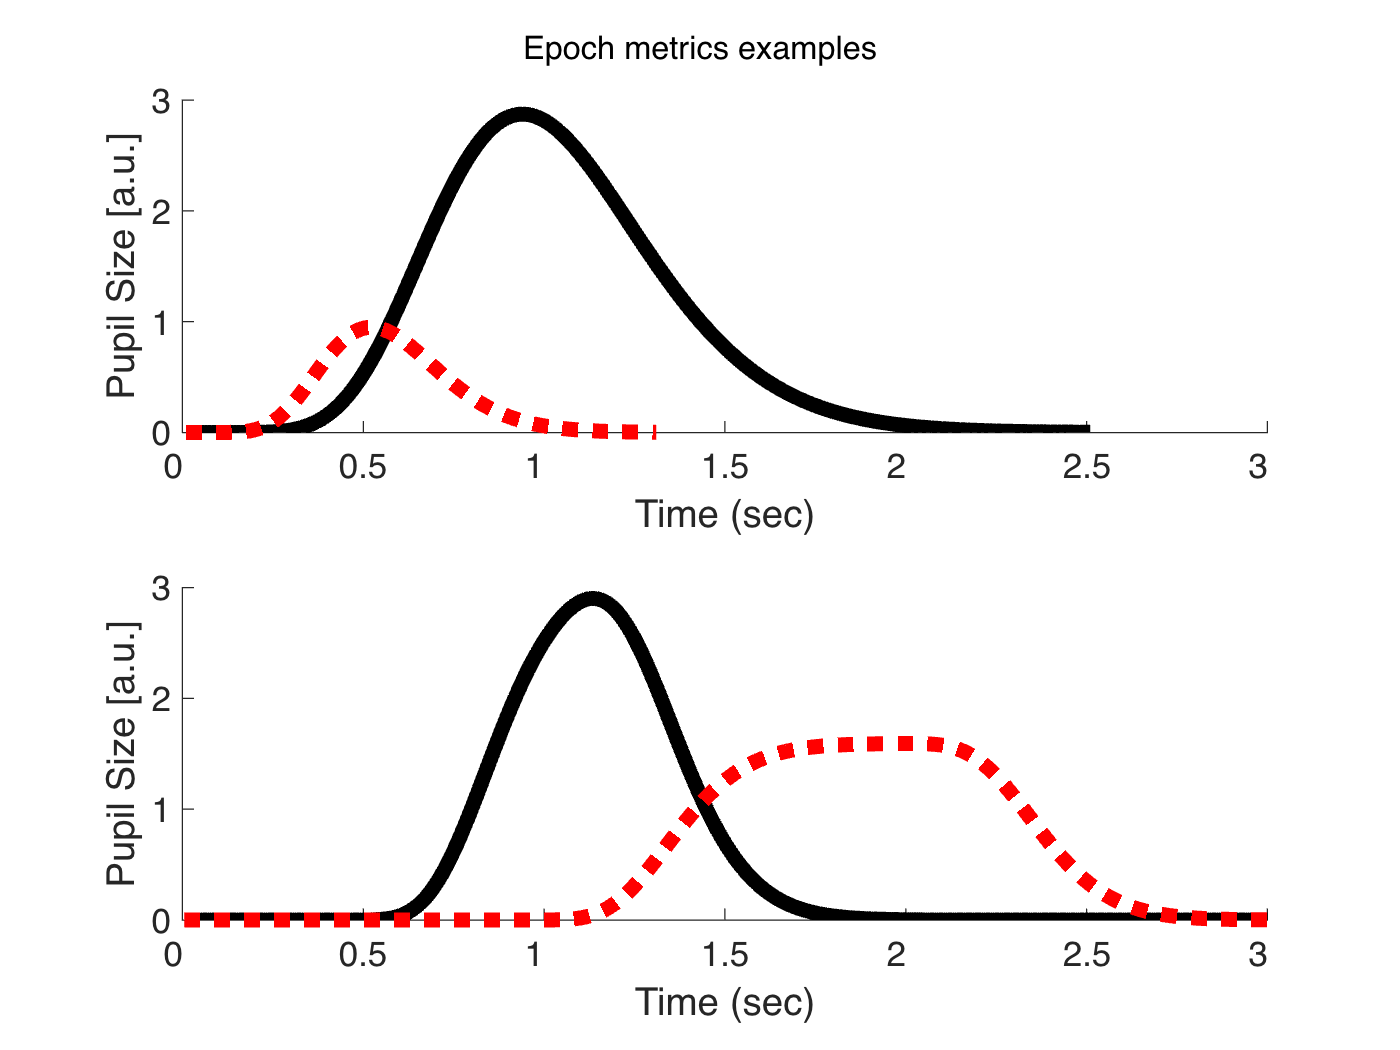


subplot(2,1,2)
plot(pw1, 'k', 'LineWidth', lw)
hold on 
plot(pw2, ':r', 'LineWidth', lw)
xt = get(gca,'xtick');    
set(gca,'XTick',xt, 'xticklabel',xt/100/2)
xlabel('Time (sec)')
ylabel('Pupil Size [a.u.]')
set(gca,'box','off')
set(gca, 'Fontsize', fsize)
sgtitle('Epoch metrics examples')

## Figure 3

Examples of signal-to-signal comparisions one might wish to make

Recorded vs. predicted pupil data:

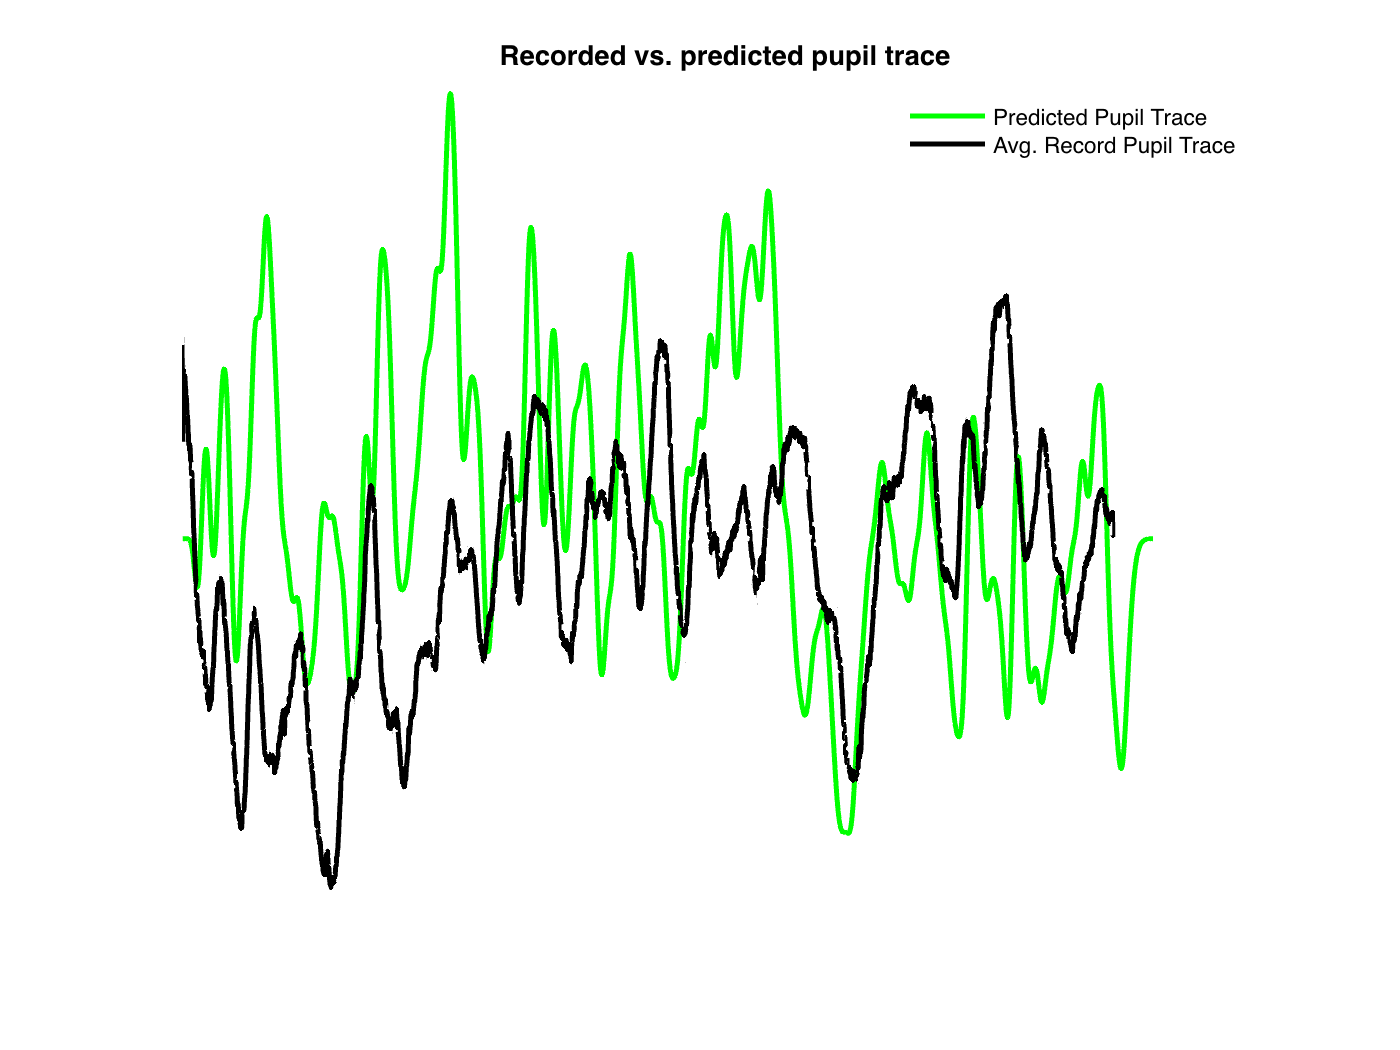

figure()
yyaxis left
plot(pred, 'g', 'Linewidth', 2)
axis off
hold on
yyaxis right
plot(avgpup, 'k', 'Linewidth', 2)
axis off 
legend('Predicted Pupil Trace', 'Avg. Record Pupil Trace', 'Box', 'Off')
title('Recorded vs. predicted pupil trace')

Pupil data for all participants, one stimulus

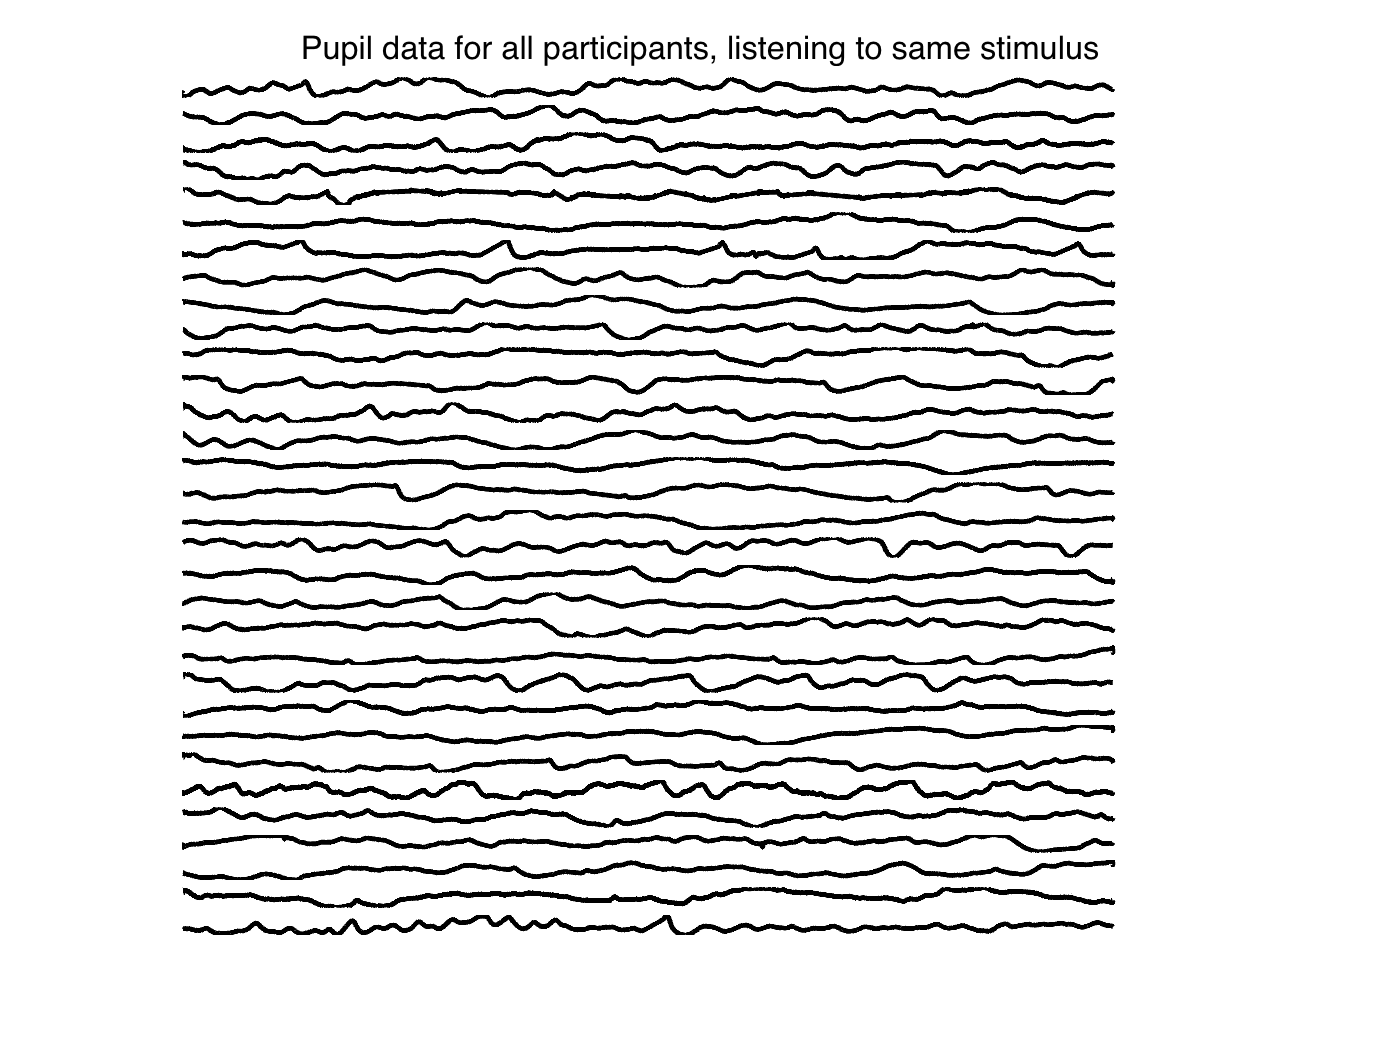

% Get pupil data for each participant
singlesub = cell2mat(pd.data.pupil(stim_mask)); 

% plot
figure()
nsubs = size(singlesub,1);
for isub = 1:nsubs
    subplot(nsubs,1,isub)
    plot(singlesub(isub,:), 'k', 'Linewidth', 2)
    hold on 
    %ylim([-6 6])
    axis off 
end
sgtitle('Pupil data for all participants, listening to same stimulus')

Simulated data for one participant, same stimulus

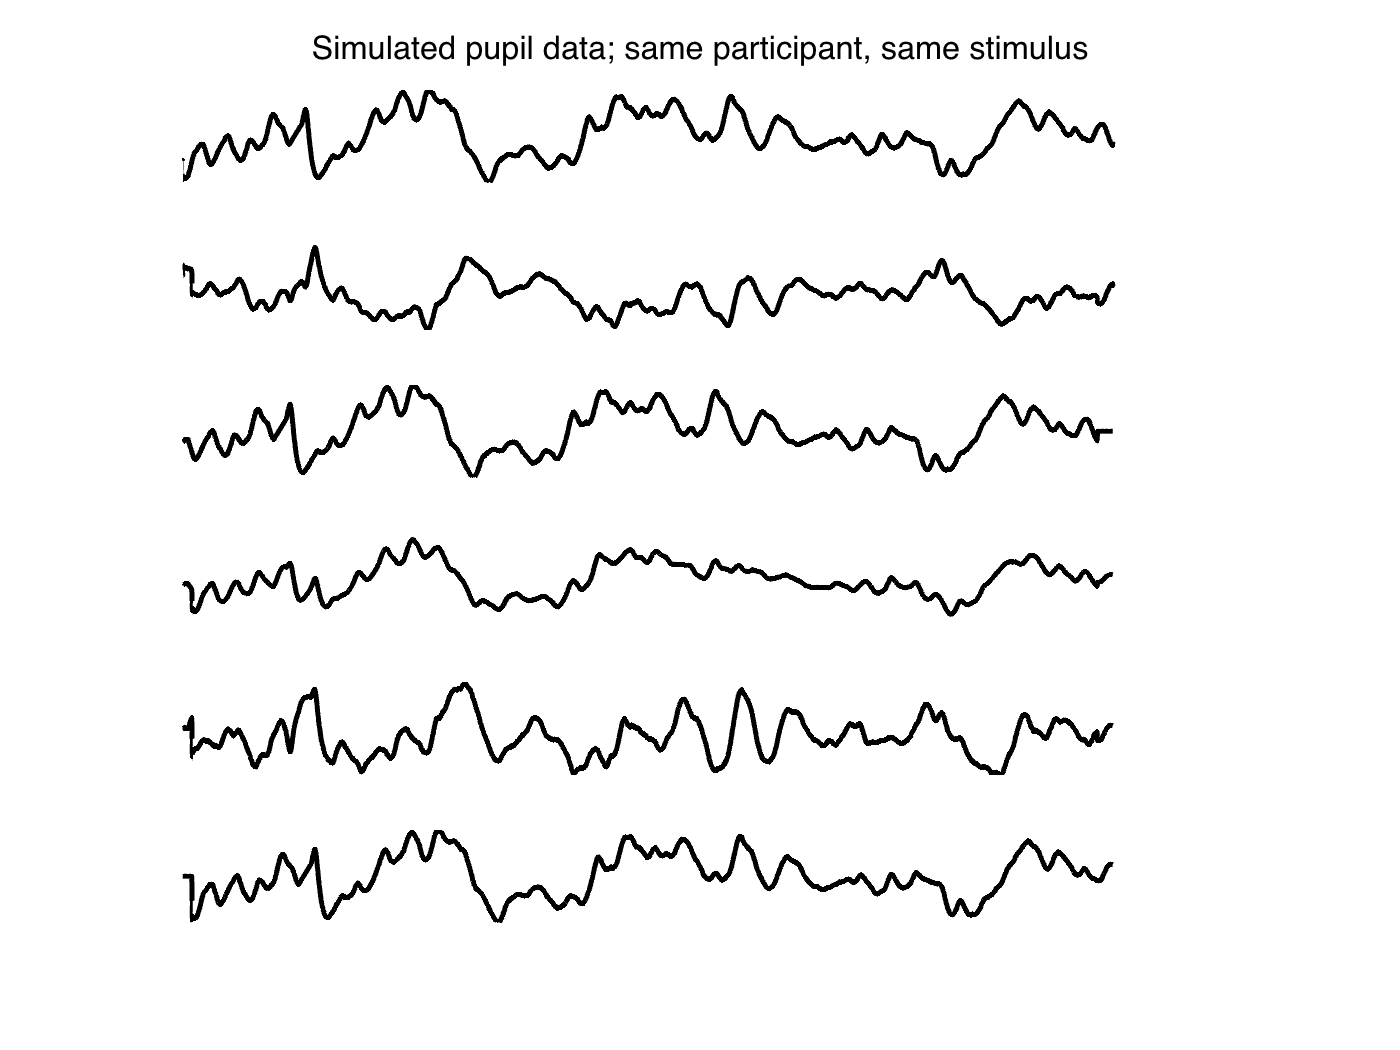

% Create different versions of pupil data
x = singlesub(1,:);
shiftforward = zeros(size(x));
shiftback = zeros(size(x));
shift = 30;
shiftforward(shift+1:end) = x(1:end-shift);
shift = -50;
shiftback(1:end+shift) = x(-shift+1:end);

another = shiftforward + shiftback;
another1 = shiftforward - shiftback;
another2 = shiftforward - (shiftback+x);

% Organize all versions we want to plot
toplot = [x; another2; shiftback; another; another1; shiftforward];

% Plot
figure()
for ip = 1:size(toplot, 1)
    subplot(6,1,ip)
    plot(toplot(ip,:), 'k', 'Linewidth', 2)
    axis off
    hold on
end

sgtitle('Simulated pupil data; same participant, same stimulus')

## Figure 4: Correlation & Dynamic Time Warping

Our first examples of signal-to-signal approaches revolve around how to relate changes in one signal with changes in another. For this purposes we can use correlation and its many variants. 

We might also be interested in properly aligning our two signals of interest (in this case pupil trace and music) by using cross-correlation or dynamic time warping. Please read Sections 3.3 - 3.5 of the paper. 

First, let's plot our two signals of interest. The pupil and the amplitude envelope of our music excerpt.

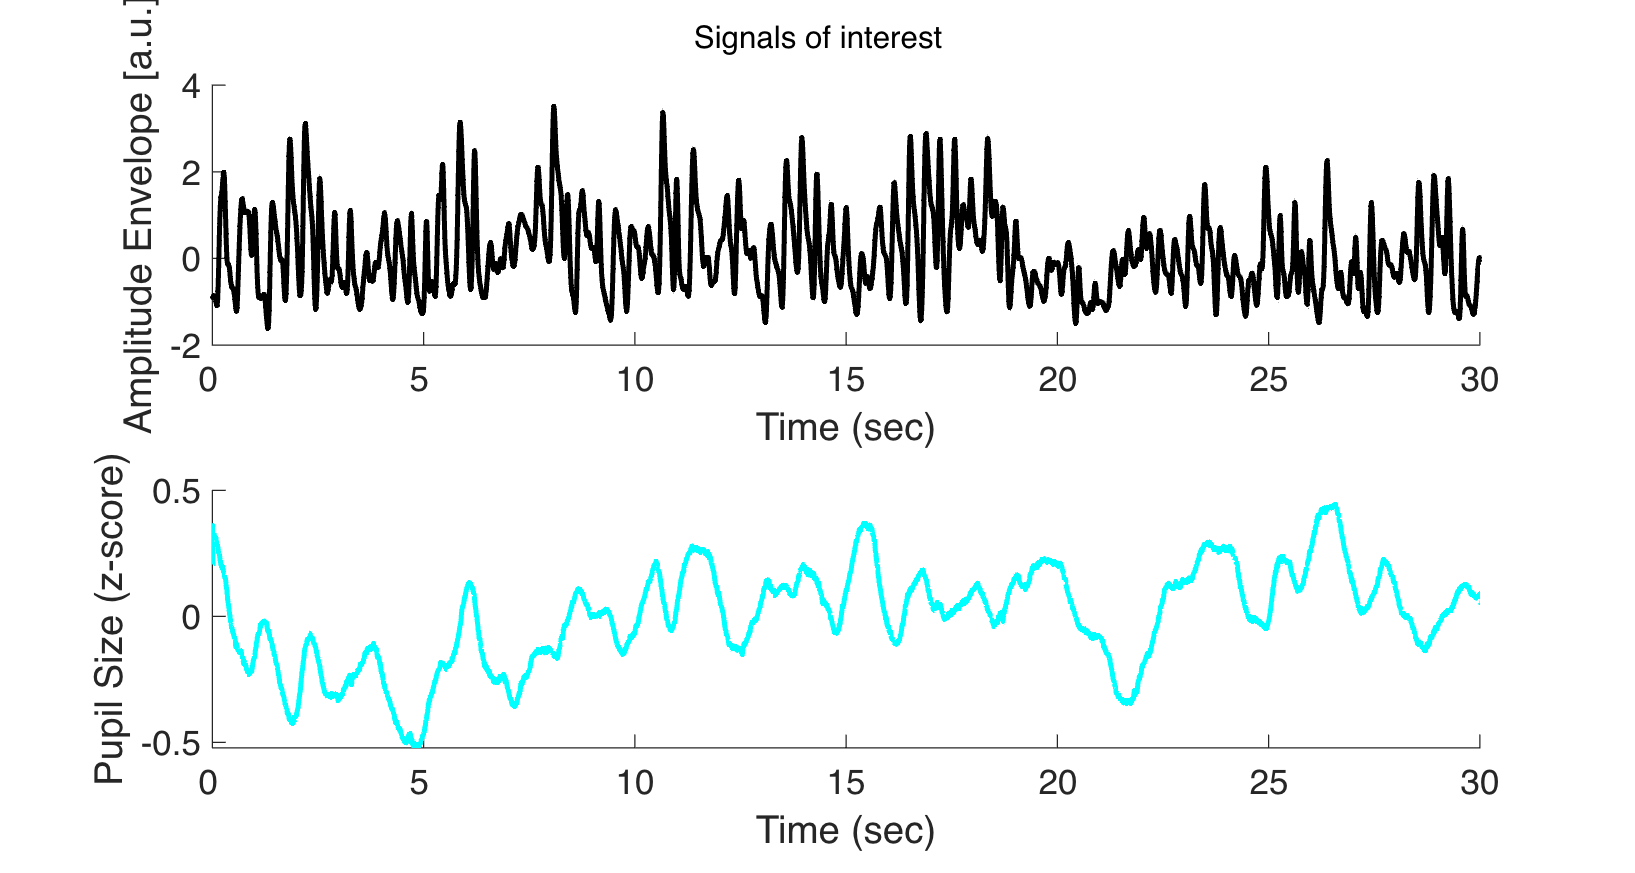

% Constants
lw = 2; % linewidth for all lines
fsize = 14; % fontsize for all text

figure()
subplot(2,1,1)
plot(music_excerpt, '.k', 'LineWidth', lw)
hold on
plot(music_excerpt, 'k', 'LineWidth', lw)
xlim([0 3000])
xt = get(gca,'xtick');
set(gca,'XTick',xt, 'xticklabel',xt/pd.pupil_info.Fs.cleaned)
xlabel('Time (sec)')
ylabel('Amplitude Envelope [a.u.]')
set(gca, 'Fontsize', fsize)
set(gca,'box','off')
hold on

subplot(2,1,2)
plot(avgpup,'c', 'LineWidth', lw)
xlim([0 3000])
xt = get(gca,'xtick');
set(gca,'XTick',xt, 'xticklabel',xt/pd.pupil_info.Fs.cleaned)
xlabel('Time (sec)')
ylabel('Pupil Size (z-score)')
set(gca, 'Fontsize', fsize)
set(gca,'box','off')
set(gcf,'Units', 'inches', 'Position',[1 1 15 8])
sgtitle('Signals of interest')

#### Correlation

avgpup = avgpup'; % corr operations need column vectors
[r_corr, p_corr] = corrcoef(music_excerpt, avgpup)

r_corr =     1.0000   -0.0573
   -0.0573    1.0000


p_corr =     1.0000    0.0017
    0.0017    1.0000


#### Moving correlation

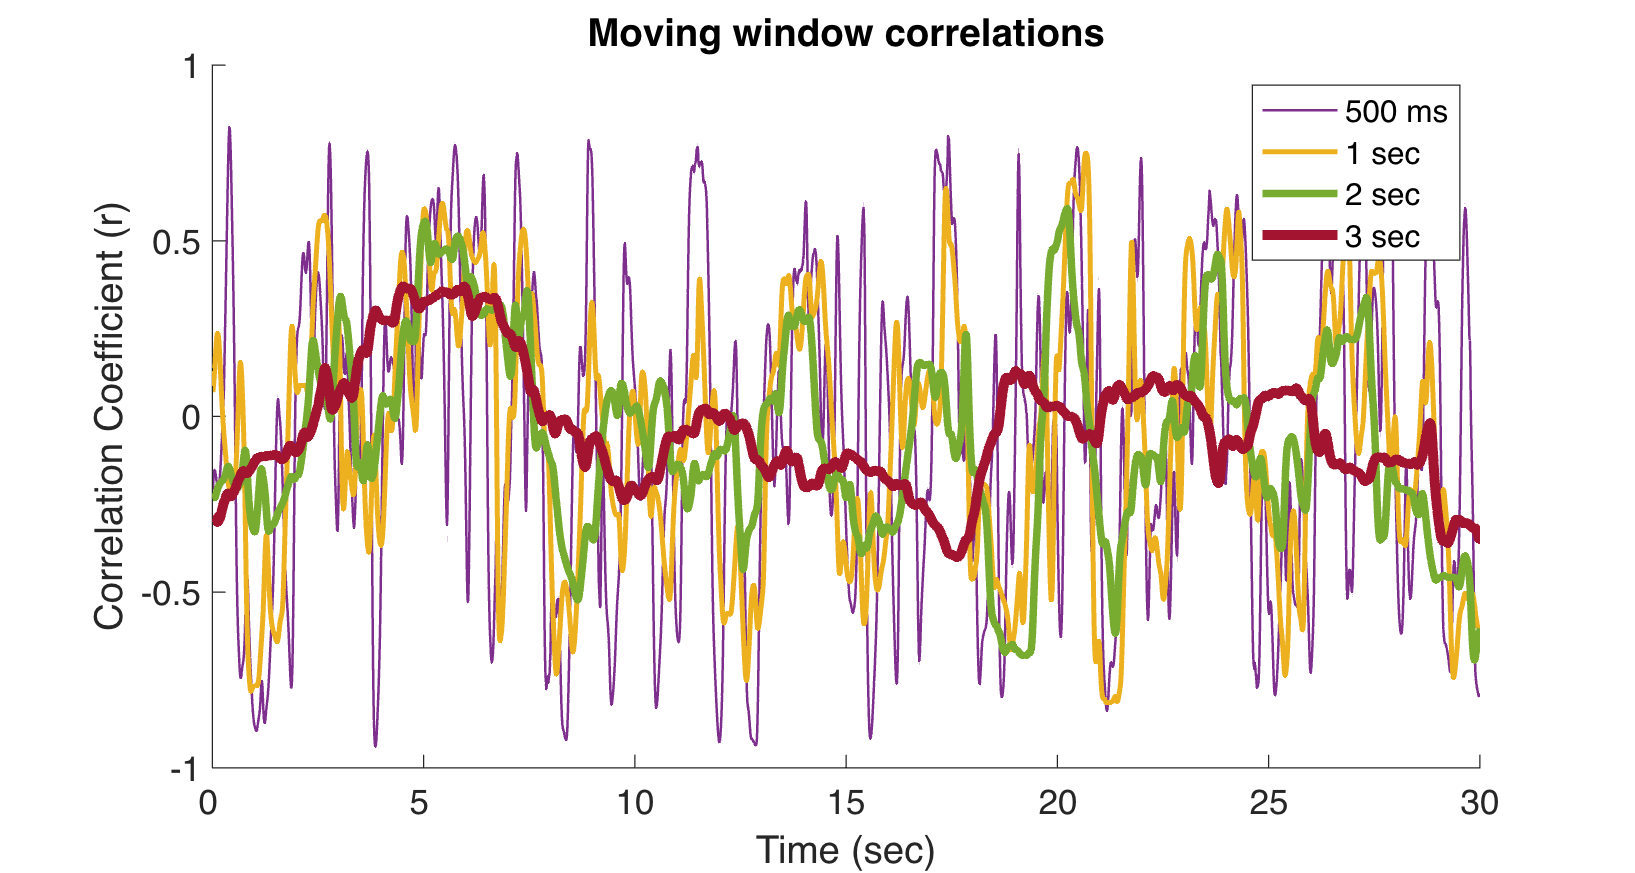

% NOTE: using 3rd party movcorr function
[r500, p500] = movcorr(music_excerpt, avgpup, 50); % 500 ms window
[r1, p1] = movcorr(music_excerpt, avgpup, 100); % 1 sec window
[r2, p2] = movcorr(music_excerpt, avgpup, 100*2); % 2 sec window
[r3, p3] = movcorr(music_excerpt, avgpup, 100*5); % 3 sec window

figure()

plot(r500, 'Color', '#7E2F8E', 'LineWidth', 1)
hold on

plot(r1, 'Color', '#EDB120', 'LineWidth', 2)
hold on

plot(r2, 'Color', '#77AC30', 'LineWidth', 3)
hold on

plot(r3, 'Color', '#A2142F', 'LineWidth', 4)
hold on

legend('500 ms', '1 sec', '2 sec', '3 sec')
xlim([0 3000])
xt = get(gca,'xtick');
set(gca,'XTick',xt, 'xticklabel',xt/pd.pupil_info.Fs.cleaned)
set(gca,'box','off')
xlabel('Time (sec)')
ylabel('Correlation Coefficient (r)')
set(gca, 'Fontsize', fsize)
set(gcf,'Units', 'inches', 'Position',[1 1 15 8])
title('Moving window correlations')

#### Cross-correlation

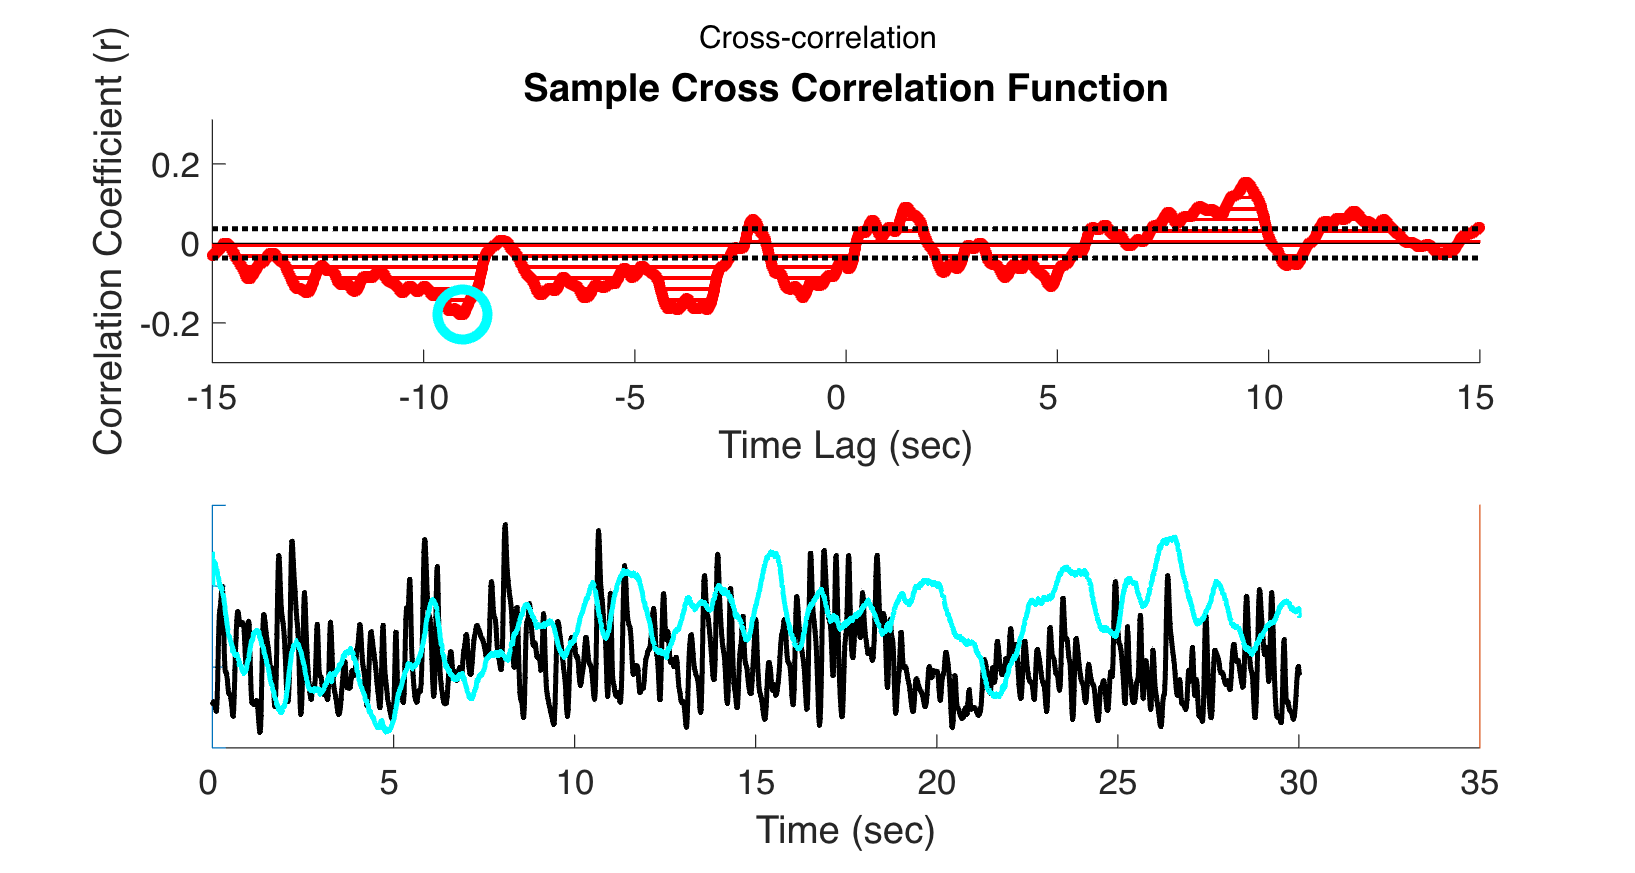

figure()
subplot(2,1,1)
[xcf,lags,bounds,h] = crosscorr(music_excerpt, avgpup, 'NumLags',1500,'NumSTD',2);
set(h(1), 'Color', 'r', 'LineStyle', ':');
set(h(2), 'Color', 'k', 'LineStyle', ':', 'LineWidth', 2);
set(h(3), 'Color', 'k', 'LineStyle', ':', 'LineWidth', 2);
xt = get(gca,'xtick');
set(gca,'XTick',xt, 'xticklabel',xt/pd.pupil_info.Fs.cleaned)
xlabel('Time Lag (sec)')
ylim([-.3 .31])
ylabel('Correlation Coefficient (r)')
set(gca,'box','off')
hold on

% find optimal lag
absxcf = abs(xcf);
lagind = find(absxcf == max(absxcf));
optlag = lags(lagind) / pd.pupil_info.Fs.cleaned;
plot(lags(lagind), xcf(lagind), 'oc', 'MarkerSize', 20, 'LineWidth', 4)
grid off
set(gcf,'Units', 'inches', 'Position',[1 1 15 8])
set(gca, 'Fontsize', fsize)

% align pupil with amp env at optimal lag
subplot(2,1,2)
pad = zeros(lags(lagind), 1);
pup2 = vertcat(pad, avgpup);
musenv2 = vertcat(music_excerpt, pad);
yyaxis left
plot(musenv2, '.-k', 'LineWidth', 2)
set(gca,'yticklabels',[])
hold on
yyaxis right
plot(pup2, 'c', 'LineWidth', 2)
xt = get(gca,'xtick');
set(gca,'XTick',xt, 'xticklabel',xt/pd.pupil_info.Fs.cleaned)
xlabel('Time (sec)')
set(gcf,'Units', 'inches', 'Position',[1 1 15 8])
set(gca,'yticklabels',[])
set(gca,'ytick',[])
set(gca, 'Fontsize', fsize)
set(gca,'box','off')
sgtitle('Cross-correlation')

#### Dynamic time-warping

figure()
fprintf('Warping Cost:')

Warping Cost:

dtw(music_excerpt, avgpup, 1000)

ans = 1.9520e+03

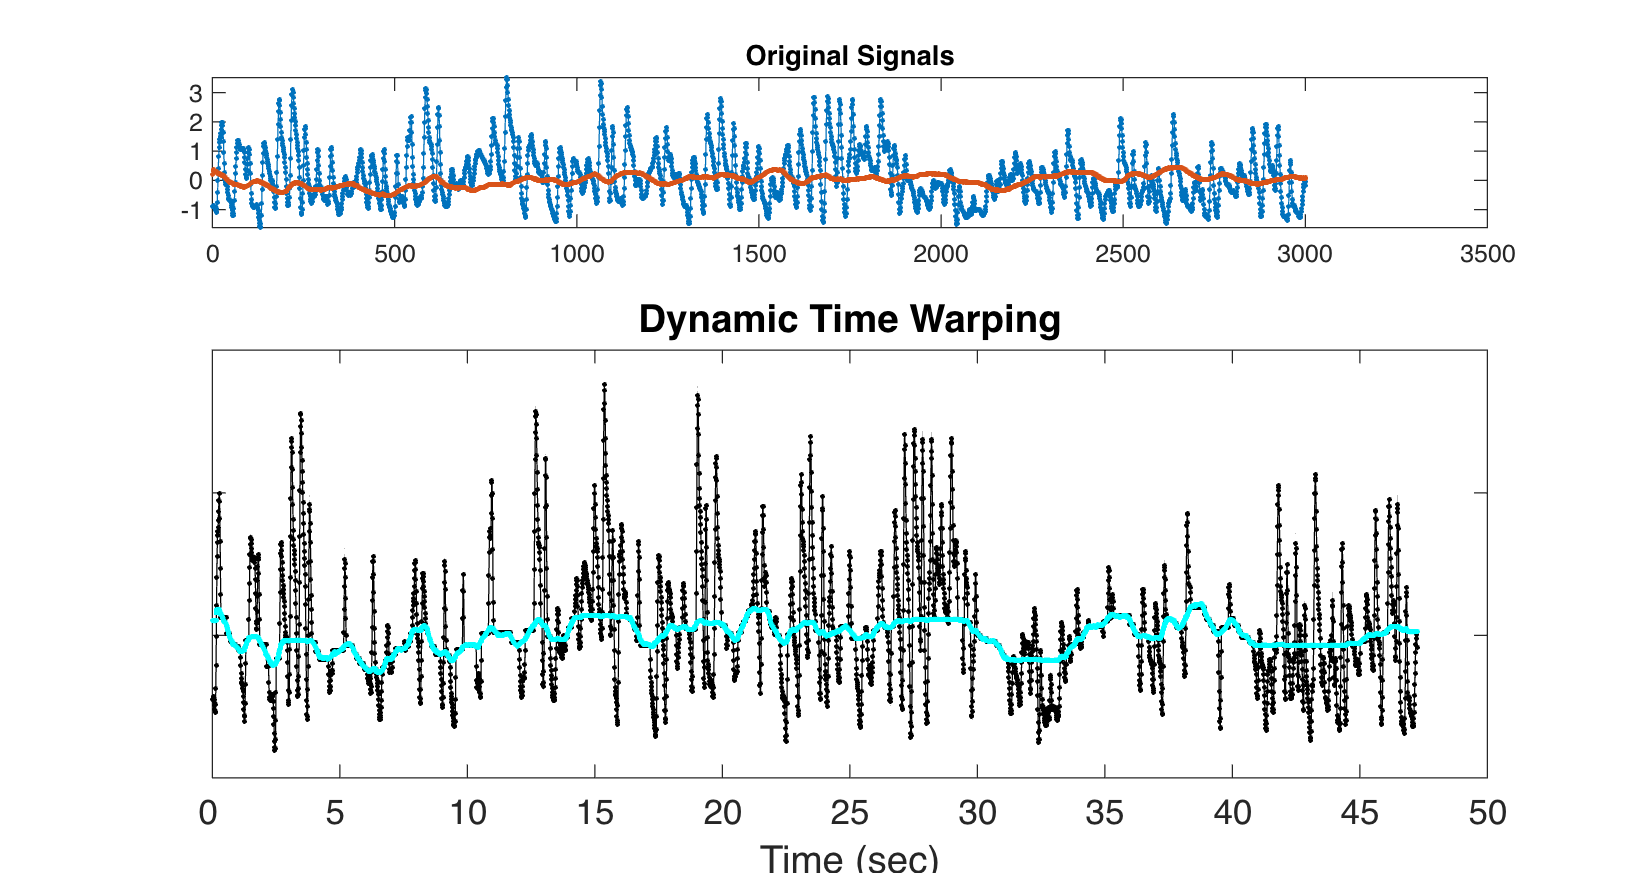

h = findobj(gca,'Type','line'); % grab auto-generated output plot
set(h(2), 'Color', 'k'); % adjust
set(h(1), 'Color', 'c', 'LineStyle', ':','LineWidth', 2);
xt = get(gca,'xtick');
set(gca,'XTick',xt, 'xticklabel',xt/pd.pupil_info.Fs.cleaned)
xlabel('Time (sec)')
set(gcf,'Units', 'inches', 'Position',[1 1 15 8])
set(gca,'yticklabels',[])
set(gca, 'Fontsize', fsize)
title('Dynamic Time Warping')

## Time-frequency analyses 

A variety of analyses fall under the heading of time-frequency analyses. We highly recommend checking out Mike X. Cohen's book, *Analyzing Neural Time Series. *It is an excellent resource for understanding core concepts and how to code them in MATLAB. Though Cohen's focus is EEG data, consider the pupil a single channel of EEG and most of the same techniques and concepts are applicable. Along with the book, Cohen also provides extensive code and video examples. 

Let's step through a few analysis approaches relevant for pupil data.

### Power spectral density

One basic thing we might want to check is whether our two signals show similar spectral profiles (i.e., energy at the same frequencies). Let's plot the spectrum of our pupil.

As stated previously, the pupil cannot change size very quickly. Our main activity of interested will be under 5 Hz. But you can use the slider to plot your frequency range of interest. 

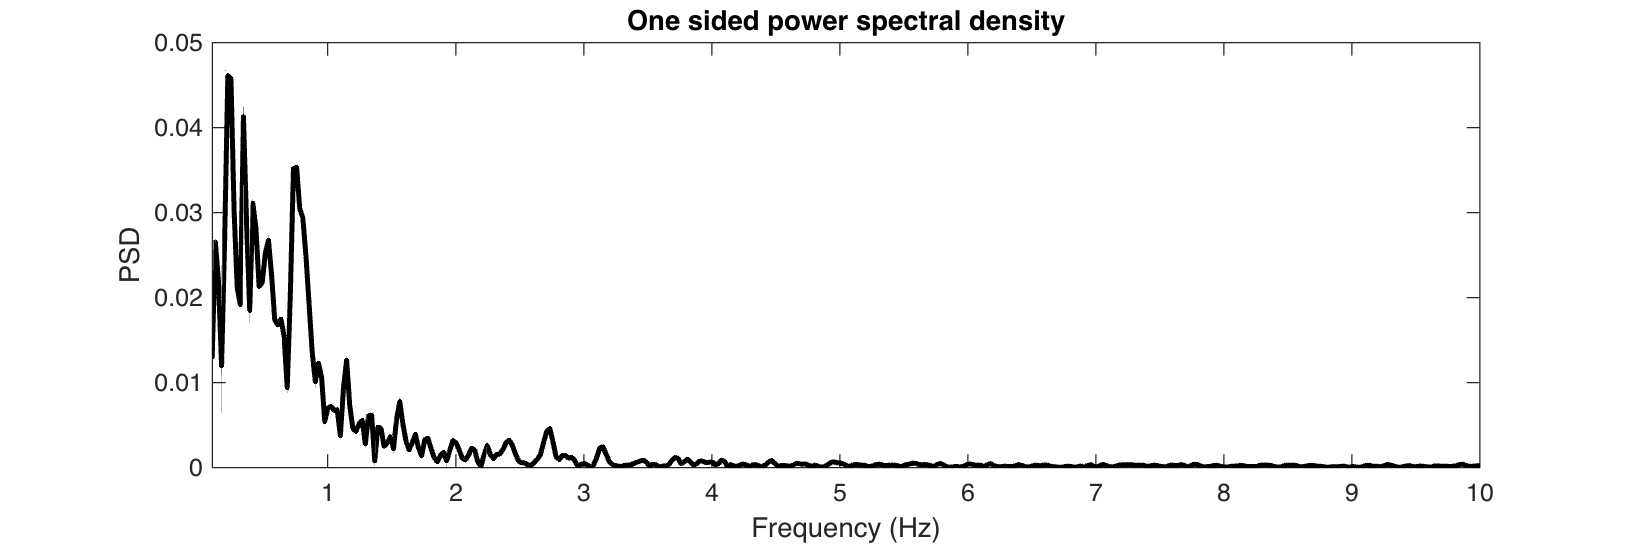

highestFreq = 10;

% Use custom function, included in this repo, to calculate FFT
[FFTresult, power, fVals] = getFFT(avgpup', pd.pupil_info.Fs.cleaned);
%[FFTresult_mus, power_mus, fVals_mus] = getFFT(music_excerpt, pd.pupil_info.Fs.cleaned);

figure()
%yyaxis left
plot(fVals, power, 'k', 'LineWidth',2);
hold on 
%yyaxis right
%plot(fVals_mus, power_mus, 'c', 'LineWidth',2);
hold on
title('One sided power spectral density');
xlabel('Frequency (Hz)')
ylabel('PSD');
xlim([0.1 highestFreq]);
set(gcf,'Units', 'inches', 'Position',[5 5 15 5])

Note that the pupil tends to follow a 1/f power law scaling function (i.e., high power at lower frequencies that decays exponentially). Nonetheless, in certain circumstances, the pupil may exhibit peaks beyond the 1/f background noise. Peaks in the plot represent increased power (y axis) at the corresponding frequency (x axis). One would need to conduct appropriate tests to be sure that a peak is significantly different from noise. Nonetheless, high spectral density at a specific frequency does not necessarily mean "entrainment" or phase-locking with a stimulus at that frequency. To understand whether the pupil is entrained to some frequency present in a stimulus, it would be necessary to do a phase-based analysis (the topic of the next section).

### Magnitude squared coherence

Magnitude squared coherence is essentially the

 correlation of the PSD (see above) of the two signals. More precisely, it is the discrete Fourier Transform (DFT) of the cross correlation function of the two signals. Because a DFT involves the assumption of stationarity, one should be careful in considering whether one’s data meet those assumptions and, if not, to use windows of an appropriate length during which stationarity can reasonably be assumed. Both the length of the window over which the DFT is calculated, as well as the overlap chosen between windows, influence the frequency resolution of the resultant power spectral density estimates.

We can compute ms coherence over the entire course of the trial (left column in plots below), or over time by calculating it within multiple windows of a shorter duration (right column in plots below). Note that inter-site phase clustering (ISPC; top row) and magnitude squared coherence (bottom row) are quite similar, except that ms coherence takes into account the power at each frequency. See sections 3.6 and 3.7 in the paper. 

### Figure 5

The code below will re-create Figure 5, exactly as shown in the paper. 

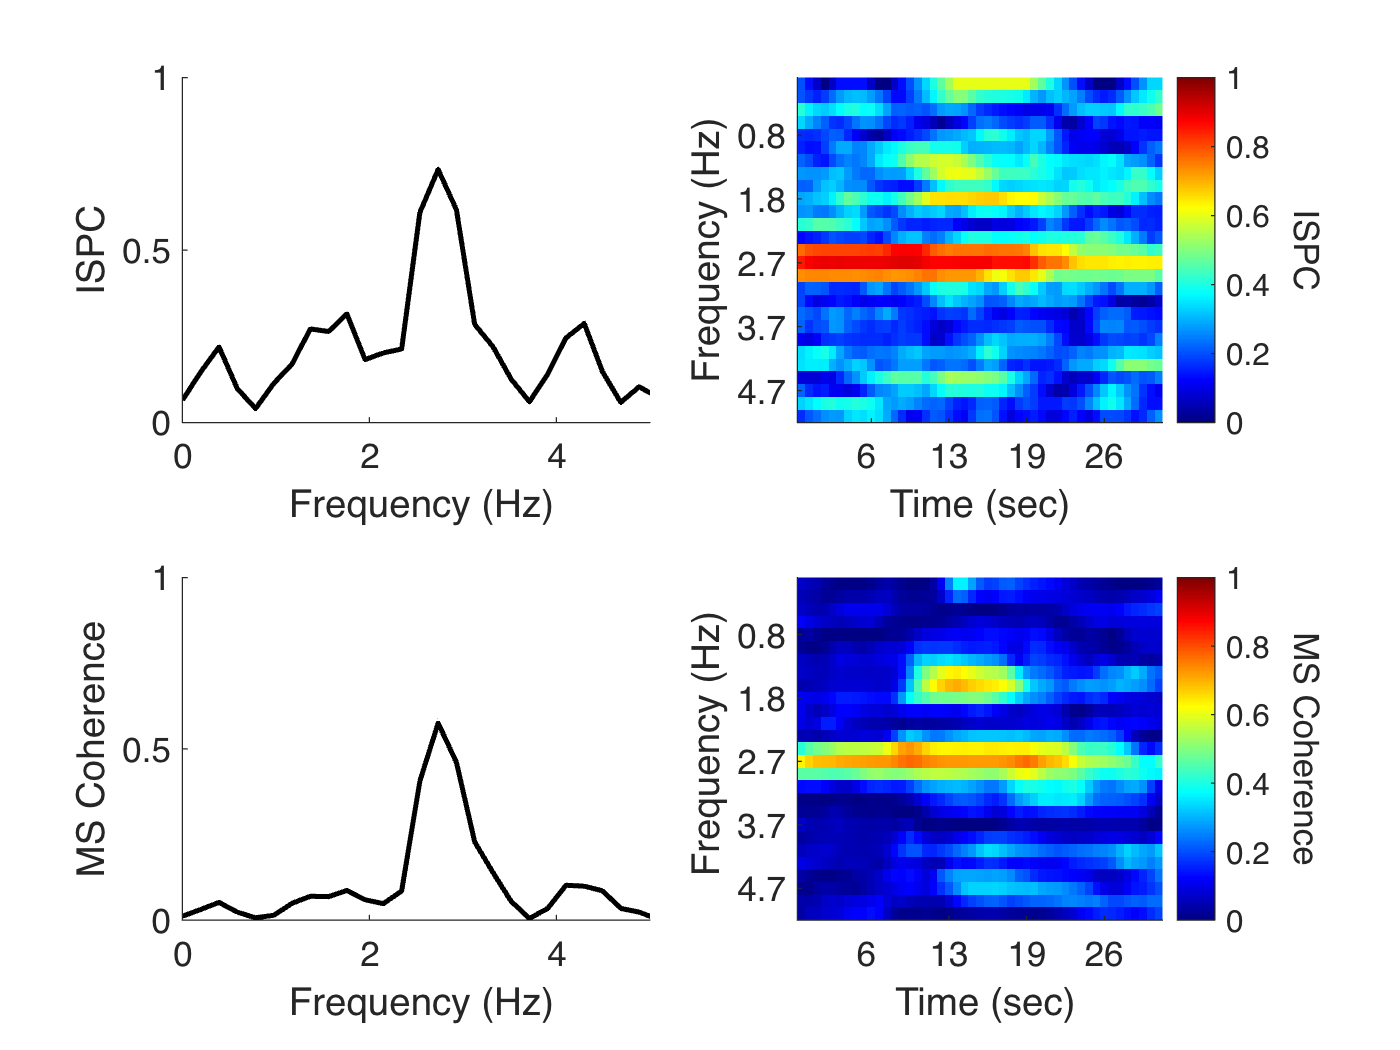

%% Figure 5: phase clustering measures
% Code from Alessandro Tavano

% constants
x = music_excerpt(1:3000); 
y = avgpup(1:3000); 
kwin = 256;
fs = pd.pupil_info.Fs.cleaned;

% get stft
[x1, f1] = stft(x,fs,'Window',kaiser(kwin,5),'OverlapLength',220,'FFTLength',512);
x1 = x1(kwin:end,:); % take pos side of result 
f1 = f1(kwin:end);

y1 = stft(y,fs,'Window',kaiser(kwin,5),'OverlapLength',220,'FFTLength',512);
y1 = y1(kwin:end,:);

% set freqs of interest for subsequent analyses
highestFreq = 5;
endind = find(f1 >= highestFreq, 1); % get index of highest freq we are interested in
freqs = 1:endind; % indices of f1


%-------------------------------------------------------------------------%
% ISPC
%-------------------------------------------------------------------------%

% ISPC
ISPC = zeros(1,numel(freqs));
for iFreq = freqs
    for iTime = 1:size(x1,2)
        temp(iTime) = exp(1i*(angle(x1(iFreq,iTime))-angle(y1(iFreq,iTime))));
    end
    ISPC(iFreq) = abs(sum(temp)./size(x1,2));
end

% ISPC over time
windowWidth = 30;
%ISPCtime = zeros(numel(freqs), size(x1,2));
for iFreq = freqs 
    for iTime = 1:size(x1,2)
        temp(iTime) = exp(1i*(angle(x1(iFreq,iTime))-angle(y1(iFreq,iTime))));
    end
    
    averagedData = zeros(1, length(temp) - windowWidth);
    for k = 1 : length(temp) - windowWidth
        averagedData = abs(sum(temp(k:k+windowWidth-1)./windowWidth));
        ISPCtime(iFreq,k) = averagedData;
    end
end


%-------------------------------------------------------------------------%
% Magnitude-Squared Coherence
%-------------------------------------------------------------------------%
Cxy = zeros(1,numel(freqs));
for iFreq = freqs 
    for iTime = 1:size(x1,2)
        temp(iTime) = abs(x1(iFreq,iTime)).*abs(y1(iFreq,iTime)).*exp(1i*(angle(x1(iFreq,iTime))-angle(y1(iFreq,iTime))));
        x1time(iTime) = x1(iFreq,iTime);
        y1time(iTime) = y1(iFreq,iTime);
    end
    Cxy(iFreq) = (abs(mean(temp)).^2)/((mean(abs(x1time).^2))*(mean(abs(y1time).^2)));
end

% MS Coherence over time
windowWidth = 30;
%Cxytime = zeros(numel(freqs), size(x1,2));
for iFreq = freqs 
    for iTime = 1:size(x1,2)
        temp(iTime) = abs(x1(iFreq,iTime)).*abs(y1(iFreq,iTime)).*exp(1i*(angle(x1(iFreq,iTime))-angle(y1(iFreq,iTime))));
        x1time(iTime) = x1(iFreq,iTime);
        y1time(iTime) = y1(iFreq,iTime);
    end
    
    averagedData = zeros(1, length(temp) - windowWidth);
    for k = 1 : length(temp) - windowWidth
        averagedData = (abs(mean(temp(k:k+windowWidth-1))).^2)/((mean(abs(x1time(k:k+windowWidth-1).^2)))*(mean(abs(y1time(k:k+windowWidth-1).^2))));% abs(sum(temp(k:k+windowWidth-1)./windowWidth));
        Cxytime(iFreq,k) = averagedData;
    end
end

%-------------------------------------------------------------------------%
% Plots ISPC and MS Cohere
figure()
lw = 2; % linewidth for all lines
fsize = 14; % fontsize for all text
colormap(jet)

% ISPC
subplot(2,2,1)
plot(f1(freqs), ISPC, 'k', 'LineWidth', lw)
ylabel('ISPC')
ylim([0 1])
xlim([0 5])
xlabel(' Frequency (Hz)')
set(gca, 'Fontsize', fsize)
set(gca,'box','off')

% ISPC over time
subplot(2,2,2)
colormap(jet)
imagesc(ISPCtime)
yt = get(gca,'ytick');
set(gca,'YTick',yt, 'yticklabel',round(f1(freqs(yt)),1))
ylabel('Frequency (Hz)')
caxis([0 1])
xt = get(gca,'xtick');
time = windowWidth/size(Cxytime,2):windowWidth/size(Cxytime,2):windowWidth;
time = round(time(xt), 0);
set(gca,'XTick',xt, 'xticklabel',time)
xlabel('Time (sec)')
set(gca, 'Fontsize', fsize)
a = colorbar('EastOutside');
ylabel(a,'ISPC', 'FontSize',fsize,'Rotation',270);
a.Label.Position(1) = 4;
set(gca,'box','off')


% MS Coherence
subplot(2,2,3)
plot(f1(freqs), Cxy, 'k', 'LineWidth', lw)
ylabel('MS Coherence')
ylim([0 1])
xlim([0 5])
xlabel(' Frequency (Hz)')
set(gca, 'Fontsize', fsize)
set(gca,'box','off')

% coherence over time
subplot(2,2,4)
imagesc(Cxytime)
ylabel('Coherence')
yt = get(gca,'ytick');
set(gca,'YTick',yt, 'yticklabel',round(f1(freqs(yt)),1)) 
ylabel(' Frequency (Hz)')
caxis([0 1])
xt = get(gca,'xtick');
time = windowWidth/size(Cxytime,2):windowWidth/size(Cxytime,2):windowWidth;
time = round(time(xt), 0);
set(gca,'XTick',xt, 'xticklabel',time)
xlabel(' Time (sec)')
set(gca, 'Fontsize', fsize)
a = colorbar('EastOutside');
ylabel(a,'MS Coherence', 'FontSize',fsize,'Rotation',270);
a.Label.Position(1) = 4;
set(gca,'box','off')

For stimulus 20, in the above two plots, we can see a clear peak in phase coherence at ~2.7 Hz, which turns out to be the perceived beat frequency in this music. For stimulus 6, on the other hand, there does not appear to be much phase consistency between the music and the pupil. Do you have any ideas why? Remember, you can listen to both stimuli, and change which one is plotted, by using the controls towards the top of the script. Remember though, that here we are only analyzing the 30 second window from seconds 5-35 of the stimuli. 

## Figure 6: Detrended Fluctuation Analysis (DFA)

Please see Section 3.8 in the paper for discussion of DFA. Note that the function included in this repository does not use overlapping windows, but users might well want to use overlapping windows. 

% dfa
data = pd.data.pupil{1}; % do this for one subject's data
minwinsize = 50; % .5 sec
maxwinsize = floor(numel(data)*.10); % 10% of data length
numwins = 10;
pts = linspace(log10(minwinsize), log10(maxwinsize), numwins); % generate 10 evenly sampled pts in log space
for i = 1:length(pts)
    pts(i) = 10^pts(i);
end
pts = ceil(pts);
fordfa = cumsum(data); % get cum sum of our pupil data
order = 1; % default dfa order 
[alpha,F] = DFA_fun(data,pts,order); % run dfa
% NOTE: this function does not use overlapping windows
plot_fun = @(xp,A,ord) polyval(A,log10(xp));
fprintf('alpha: %f', alpha(1)) % our alpha exponent result, A(2) = intercept of regression

alpha: 1.463849

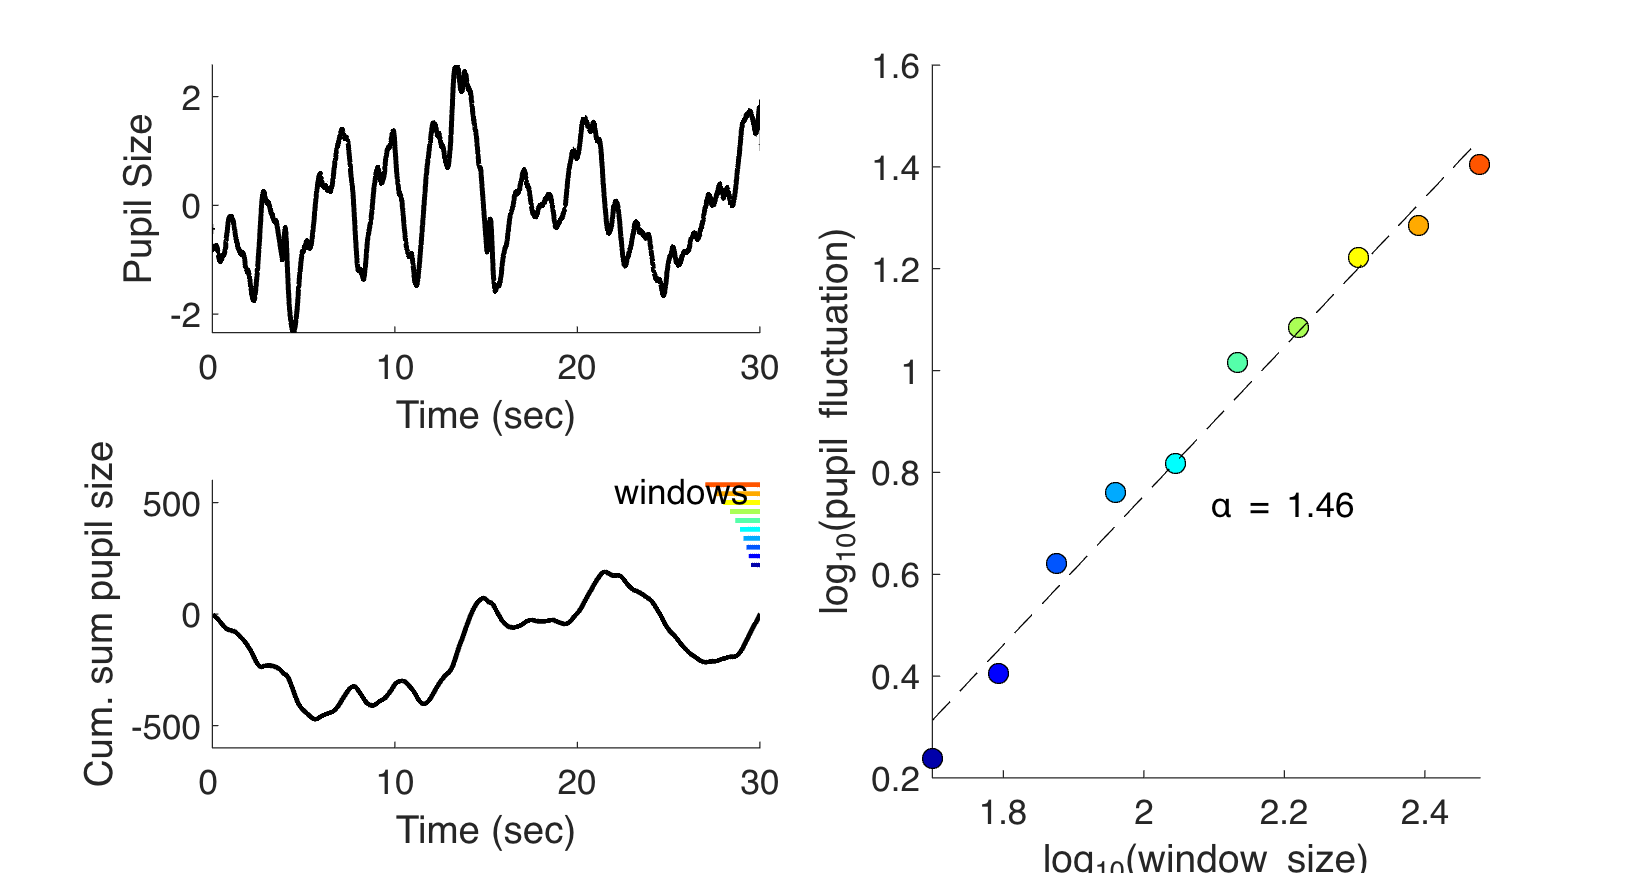

% plot
figure()
subplot(2,2,1)
plot(data, 'k', 'LineWidth', lw)
ylabel('Pupil Size')
xlim([0 3000])
xt = get(gca,'xtick');
set(gca,'XTick',xt, 'xticklabel',xt/pd.pupil_info.Fs.cleaned)
xlabel('Time (sec)')
set(gca, 'Fontsize', fsize)
%set(gca,'yticklabels',[])
set(gca,'box','off')

subplot(2,2,3)
plot(fordfa, 'k', 'LineWidth', lw)
ylabel('Cum. sum pupil size')
xlim([0 3000])
xt = get(gca,'xtick');
set(gca,'XTick',xt, 'xticklabel',xt/pd.pupil_info.Fs.cleaned)
xlabel('Time (sec)')
hold on
% plot windows sizes
ylim([-600 600])
linepts = linspace(220, 580, 10);
cmap = colormap(jet(numel(pts)));
for i = 1:numel(pts)
    plot(numel(fordfa)-pts(i):numel(fordfa)-1, repelem(linepts(i), pts(i)), 'Color',cmap(i,:), 'LineWidth', lw)
    %plot(1:pts(i), repelem(linepts(i), pts(i)), 'Color',cmap(i,:), 'LineWidth', lw)
    hold on
end
set(gca, 'Fontsize', fsize)
%set(gca,'yticklabels',[])
set(gca,'box','off')
txt = strcat('windows');
text(2200,550,txt, 'Fontsize', fsize)

subplot(2,2,[2,4])
for i = 1:numel(pts)
    plot(log10(pts(i)),log10(F(i)), 'o', 'MarkerFaceColor',cmap(i,:), 'MarkerEdgeColor', 'k', 'MarkerSize', 8) %cmap(i,:)) % plot fluctuation in each window
    hold on
end
plot(log10(pts),plot_fun(pts,alpha),'k--')
xlabel('log_{10}(window size)')
ylabel('log_{10}(pupil fluctuation)')
set(gca, 'Fontsize', fsize)
txt = strcat('\alpha = ', 32, num2str(round(alpha(1),2))); % 32 is space character
posx = mean(log10(pts));
posy = alpha(1) /2;
text(posx,posy,txt, 'Fontsize', fsize)

set(gcf,'Units', 'inches', 'Position',[1 1 15 8])
set(gca,'box','off')

TODO - do we need to add a figure or at least an output value for DCCA between pupil and music? 

## Figure 7: Recurrance Quantification Analysis (RQA & CRQA)

TODO integrate Sebastian's R code into MATLAB... 

## Additional resources

Choosing appropriate analysis techniques, window sizes, etc., will depend not only on your understanding of the technique but also on the length of your recorded data, the type of task participants were doing, the design of your experiment, and so on. Please consult the resources above for more information about analysis techniques. For more information about best practices in pupillometry, in general, please consult the following:

Steinhauer, S. R., Bradley, M. M., Siegle, G. J., Roecklein, K. A., & Dix, A. (2022). Publication guidelines and recommendations for pupillary measurement in psychophysiological studies. *Psychophysiology*, *59*(4), e14035.

Laeng, B., & Alnaes, D. (2019). Pupillometry. In *Eye movement research* (pp. 449-502). Springer, Cham.

Mathôt, S. (2018). Pupillometry: Psychology, physiology, and function. *Journal of Cognition*, *1*(1).